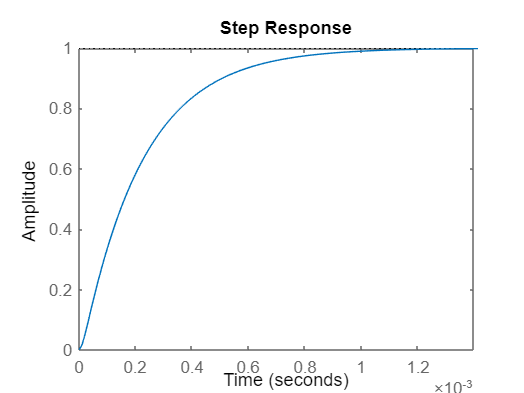

% Ex.7
clear variables

% c)

R1 = 2.7e3;
R2 = 20e3;
C1 = 10e-9;
C2 = 4.7e-9;
H = tf(1/R1/R2/C1/C2,[1,(R1+R2)/R1/R2/C2,1/R1/R2/C1/C2]);
step(H);


%d)
k = 1; %factorul de proportionalitate
wn = zeros(1,12); %pulsatia naturala
df = zeros(1,12); %damping factor
tmax = zeros(1,12); %peak time
sigma = zeros(1,12);%suprareglajul
tr = zeros(1,12);%timpul de raspuns
tu = zeros(1,12);%timpul de urcare
C2_1 = [15e-9 22e-9 28e-9 33e-9 47e-9 56e-9 68e-9 150e-9 220e-9 280e-9 330e-9 470e-9];

for i=1:length(C2_1)
    wn(i) = sqrt(1/R1/R2/C1/C2_1(i));
    df(i) = (R1+R2)/R1/R2/C2_1(i)*1/2/wn(i);
    tmax(i) = pi/wn(i)/sqrt(1-df(i)^2);
    sigma(i) = k*exp(-pi*df(i)/sqrt(1-df(i)^2));
    tr(i) = 4/df(i)/wn(i);
    tu(i) = 2.2/df(i)/wn(i);
end
df

df =     1.2611    1.0413    0.9230    0.8502    0.7124    0.6527    0.5923    0.3988    0.3293    0.2919    0.2689    0.2253


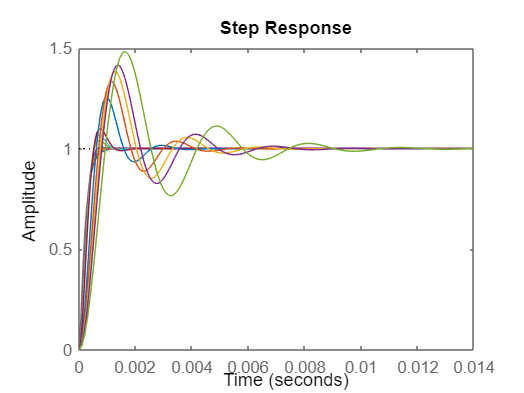


%e
for j = 1:length(C2_1)
    H(j) = tf(1/R1/R2/C1/C2_1(j),[1,(R1+R2)/R1/R2/C2_1(j),1/R1/R2/C1/C2_1(j)]);
    step(H(j));
    hold on;
end